% 假设 M, K, r 已定义，r 是激励方向向量
index1 = [1,4];
index2 = [2,3,5,6];
r0=MPrt([index1,index2],[index1,index2])*[1,1,1,1,1,1]';
r = r0;
%r=[1,0,0,1,0,0,1,0,0,1,0,0,1,0,0,1,0,0]';
order = [index1,index2];
K = KPrt(order,order);
M = MPrt(order,order);
[phi, omega2] = eig(K, M);   % 计算模态
omega = sqrt(diag(omega2))

omega =    26.5540
  104.9645
  191.1624
  223.5710
  274.5714
  300.2977



n = size(phi, 2);
Gamma = zeros(n, 1);

for i = 1:n
    phi(:,i) = phi(:,i) / sqrt(phi(:,i)' * M * phi(:,i));  % 质量归一化
    Gamma(i) = phi(:,i)' * M * r;   % 模态参与因子
end

% 可视化参与因子或其平方
GammaSq = Gamma.^2;
participation_ratio = GammaSq / sum(GammaSq)

participation_ratio =     0.8097
    0.1559
    0.0000
    0.0300
    0.0000
    0.0044


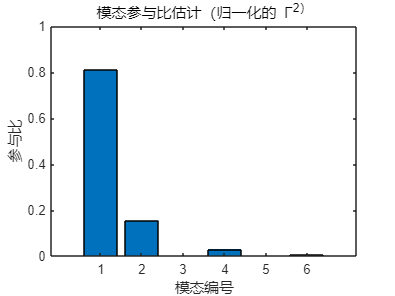

bar(participation_ratio);
xlabel('模态编号');
ylabel('参与比');
title('模态参与比估计（归一化的 Γ^2）');


% 假设 phi 是 15自由度 x n模态的矩阵，M 是 15x15的质量矩阵
m = diag(M); % 取对角元素作为等效质量

n_dof = length(m);
n_modes = size(phi, 2);

% 计算角频率 omega_i
omega = sqrt(diag(omega2));  % omega2为广义特征值矩阵

% 初始化自由度-模态能量矩阵
E = zeros(n_dof, n_modes);

for i = 1:n_modes
    for j = 1:n_dof
        E(j,i) = 0.5 * omega(i)^2 * m(j) * phi(j,i)^2;
    end
    % 对每个模态归一化
    sum(E(:,i))
    %E(:,i) = E(:,i) / sum(E(:,i));
end

ans = 352.5580

ans = 5.5088e+03

ans = 1.8272e+04

ans = 2.4992e+04

ans = 3.7695e+04

ans = 4.5089e+04

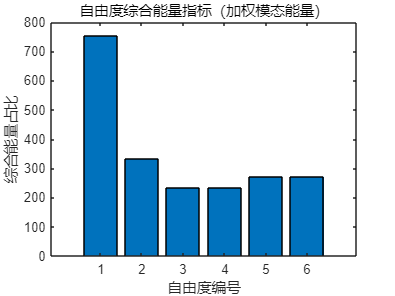


% E(:,i) 就是模态 i 下各自由度的能量分布比例

% 假设:
% E 是 n_dof x n_modes 的自由度-模态能量矩阵（每列归一化过）
% participation_ratio 是 n_modes x 1 的模态能量占比，且和为1

E_total = E * participation_ratio;  % n_dof x 1，综合能量指标

% 可视化
bar(E_total)
xlabel('自由度编号')
ylabel('综合能量占比')
title('自由度综合能量指标（加权模态能量）')

guyan能量

% 假设 M, K, r 已定义，r 是激励方向向量
r=TP' *r0;
%r=[1,0,0,1,0,0,1,0,0,1,0,0,1,0,0,1,0,0]';
K = KPren;
M = MPren;
[phi, omega2] = eig(K, M);   % 计算模态
omega = sqrt(diag(omega2))

omega =    27.0378
  114.1432



n = size(phi, 2);
Gamma = zeros(n, 1);

for i = 1:n
    phi(:,i) = phi(:,i) / sqrt(phi(:,i)' * M * phi(:,i));  % 质量归一化
    Gamma(i) = phi(:,i)' * M * r;   % 模态参与因子
end

% 可视化参与因子或其平方
GammaSq = Gamma.^2;
participation_ratio = GammaSq / sum(GammaSq)

participation_ratio =     0.8049
    0.1951


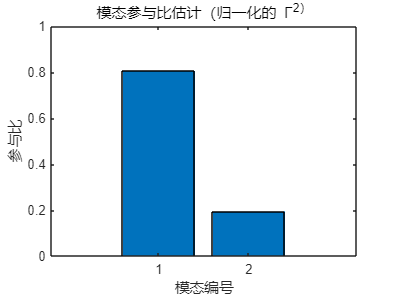

bar(participation_ratio);
xlabel('模态编号');
ylabel('参与比');
title('模态参与比估计（归一化的 Γ^2）');

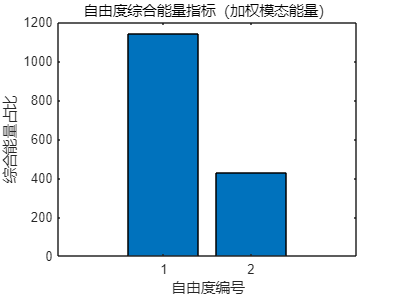


% 假设 phi 是 15自由度 x n模态的矩阵，M 是 15x15的质量矩阵
m = diag(M); % 取对角元素作为等效质量

n_dof = length(m);
n_modes = size(phi, 2);

% 计算角频率 omega_i
omega = sqrt(diag(omega2));  % omega2为广义特征值矩阵

% 初始化自由度-模态能量矩阵
E = zeros(n_dof, n_modes);

for i = 1:n_modes
    for j = 1:n_dof
        E(j,i) = 0.5 * omega(i)^2 * m(j) * phi(j,i)^2;
    end
    % 对每个模态归一化
    %E(:,i) = E(:,i) / sum(E(:,i));
end

% E(:,i) 就是模态 i 下各自由度的能量分布比例

% 假设:
% E 是 n_dof x n_modes 的自由度-模态能量矩阵（每列归一化过）
% participation_ratio 是 n_modes x 1 的模态能量占比，且和为1

E_total_guyan = E * participation_ratio;  % n_dof x 1，综合能量指标

% 可视化
bar(E_total_guyan)
xlabel('自由度编号')
ylabel('综合能量占比')
title('自由度综合能量指标（加权模态能量）')


d = [1,2];  % 缩聚前对应自由度索引

increase_rate = (E_total_guyan - E_total(d))./ E_total(d) * 100 ;

% 显示结果
for k = 1:length(d)
    fprintf('自由度 %d -> 缩聚后自由度 %d, 能量占比增加率: %.2f%%\n', d(k), k, increase_rate(k));
end

自由度 1 -> 缩聚后自由度 1, 能量占比增加率: 51.36%
自由度 2 -> 缩聚后自由度 2, 能量占比增加率: 28.05%


cb能量

% 假设 M, K, r 已定义，r 是激励方向向量
r=TP_cb' *r0;
%r=[1,0,0,1,0,0,1,0,0,1,0,0,1,0,0,1,0,0]';
K = KP_cb;
M = MP_cb;
[phi, omega2] = eig(K, M);   % 计算模态
omega = sqrt(diag(omega2))

omega =   224.4198
  105.2268
   26.5581
  274.5714
  191.1624


n = size(phi, 2);
Gamma = zeros(n, 1);

for i = 1:n
    phi(:,i) = phi(:,i) / sqrt(phi(:,i)' * M * phi(:,i));  % 质量归一化
    Gamma(i) = phi(:,i)' * M * r;   % 模态参与因子
end

% 可视化参与因子或其平方
GammaSq = Gamma.^2;
participation_ratio = GammaSq / sum(GammaSq)

participation_ratio =     0.0018
    0.2172
    0.7810
    0.0000
    0.0000


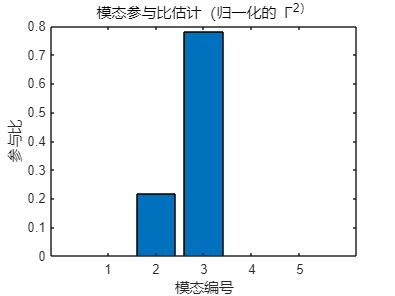

bar(participation_ratio);
xlabel('模态编号');
ylabel('参与比');
title('模态参与比估计（归一化的 Γ^2）');

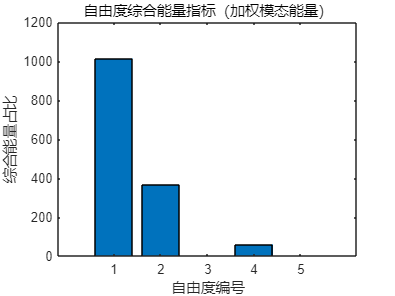


% 假设 phi 是 15自由度 x n模态的矩阵，M 是 15x15的质量矩阵
m = diag(M); % 取对角元素作为等效质量

n_dof = length(m);
n_modes = size(phi, 2);

% 计算角频率 omega_i
omega = sqrt(diag(omega2));  % omega2为广义特征值矩阵

% 初始化自由度-模态能量矩阵
E = zeros(n_dof, n_modes);

for i = 1:n_modes
    for j = 1:n_dof
        E(j,i) = 0.5 * omega(i)^2 * m(j) * phi(j,i)^2;
    end
    % 对每个模态归一化
    %E(:,i) = E(:,i) / sum(E(:,i));
end

% E(:,i) 就是模态 i 下各自由度的能量分布比例

% 假设:
% E 是 n_dof x n_modes 的自由度-模态能量矩阵（每列归一化过）
% participation_ratio 是 n_modes x 1 的模态能量占比，且和为1
d = [1,2];  % 缩聚前对应自由度索引
d2 = [1,2];

E_total_cb = E * participation_ratio;  % n_dof x 1，综合能量指标
increase_rate = (E_total_cb(d2) - E_total(d))./ E_total(d) * 100 ;

% 可视化
bar(E_total_cb)
xlabel('自由度编号')
ylabel('综合能量占比')
title('自由度综合能量指标（加权模态能量）')


% 显示结果
for k = 1:length(d)
    fprintf('自由度 %d -> 缩聚后自由度 %d, 能量占比增加率: %.2f%%\n', d(k), k, increase_rate(k));
end

自由度 1 -> 缩聚后自由度 1, 能量占比增加率: 34.81%
自由度 2 -> 缩聚后自由度 2, 能量占比增加率: 9.70%


总能量

energy_sum_guyan = sum(E_total_guyan);
%energy_sum_orig = sum(E_total(d));
energy_sum_orig = sum(E_total);
total_increase_guyan = (energy_sum_guyan - energy_sum_orig)./ energy_sum_guyan * 100

total_increase_guyan = -33.7706


energy_sum_cb = sum(E_total_cb);
%energy_sum_orig = sum(E_total(d));
total_increase_cb = (energy_sum_cb - energy_sum_orig)./ energy_sum_guyan * 100

total_increase_cb = -41.7441